# getting it right

clear
load('dgp.mat')
[n,k]= size(X);
n_knots = 9; %internal

step = floor(n/n_knots);
offset = floor((n-step*(n_knots-1))/2)+1;
indecies = [1 offset:step:n-1 n];
knots = X(indecies);

lambda = 0.05;
order =4;

## Regression Cubic Spline

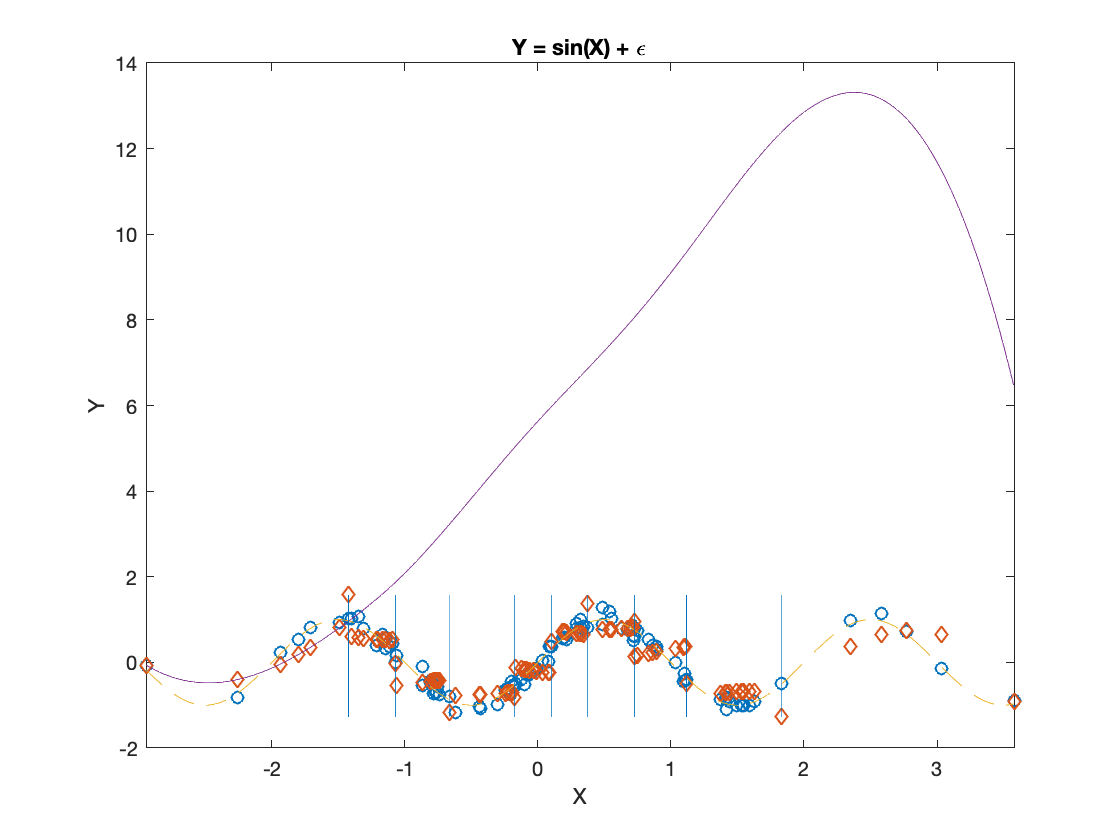

%hard coded, will work on extensible later

diff = knots(2:end)-knots(1:end-1);
RS = zeros(n,n);
H = eye((n_knots+1)*order);

%start from the bottom up
for down = n_knots+1:-1:2
    up = n_knots+1-down;
    
    subH = zeros(order-1,order);
    h = diff(down);
    for j=order:-1:2
       subH(j-1,1:j) = factorial(order-1:-1:order-j)...
           ./factorial(j-1:-1:0).*h.^[j-1:-1:0]...
           /factorial(order-j);         
    end
    
    [rows cols] = size(H);
    newCols = cols-order+1;
    newH = zeros(cols,newCols);

    E = eye(newCols);
    
    newH(1:newCols-up,1:newCols-up) = ...
        E(1:newCols-up,1:newCols-up);
    newH(end-order+2-up:end-up,:) = [zeros(order-1, ...
        newCols-order-up) subH zeros(order-1, up)];
    newH(end-up+1:end,:) = E(newCols-up+1:end,:);
    H = H*newH;
end

G = zeros(n,(n_knots+1)*order);
for i=1:n_knots+1
    start = indecies(i);
    stop = indecies(i+1);
    for j = 1:order
        G(start:stop,(i-1)*order+j) = ...
            (X(start:stop)-X(start)).^(order-j);
    end
end

RS = G*H*(H'*G'*G*H)^-1*H'*G';
Y_RS = RS*Y;
beta = (H'*G'*G*H)^-1*H'*G'*Y;
coef = zeros(n_knots+1, order);
coef(1,:) = beta(1:4)';
coef(2:end,1) = beta(5:end);
for i=2:n_knots+1
    h = diff(i-1);
    subH = zeros(order-1,order);
    for j=order:-1:2
       subH(j-1,1:j) = factorial(order-1:-1:order-j)...
           ./factorial(j-1:-1:0).*h.^[j-1:-1:0]...
           /factorial(order-j);         
    end
    coef(i,2:end) = subH*coef(i-1,:)';
end

pp = mkpp(knots,coef);


xx = X(1):0.01:X(n);
y_limits = [min(min(Y),min(Y_RS)) max(max(Y),max(Y_RS))];
plot(X,Y,'o',X,Y_RS,'d');
hold on;
fplot(@(x) sin(pi*x),'--');
plot(xx,ppval(pp,xx),'-')
title('Y = sin(X) + \epsilon');
%legend('Observed','Estimated', 'Truth','B-Spline Reg','Location','Best');
xlabel('X');
ylabel('Y');
xlim([X(1) X(n)]);
%ylim(y_limits);
for i=2:n_knots+1
    line([knots(i) knots(i)], y_limits); 
end
hold off;


rs_df1 = trace(RS)

rs_df1 = 13.0000

rs_df2 = n-trace(2*RS -RS*RS')

rs_df2 = 87

rs_df3 = trace(RS*RS')

rs_df3 = 13.0000

rs_df4 = trace(eye(size(RS))-RS)

rs_df4 = 87.0000

cond_RS = norm(RS)*norm(RS^-1)

cond_RS = 1.1634e+19

cond_RS_inner = norm(RS(2:end-1,2:end-1))*norm(RS(2:end-1,2:end-1)^-1)

cond_RS_inner = 2.1533e+19